# **Testing results**

read the files

fid = fopen('fun2_A.txt','r');
A = fscanf(fid,'%e ',[500,100]);
fclose(fid);

fid = fopen('fun2_b.txt','r');
b = fscanf(fid,'%e ',[500,1]);
fclose(fid);

fid = fopen('fun2_c.txt','r');
c = fscanf(fid,'%e ',[100, 1]);
fclose(fid);

### Funtion 1

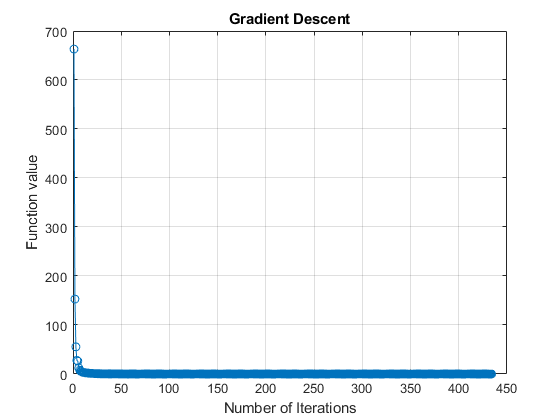

opt = 1.1851e-09

res = 	1.0e+-4 *

    0.3428
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


x1 = randn(100,1);
[opt, res] = gradDesc(@f1, @g1, x1, 0.5, 1e-4)

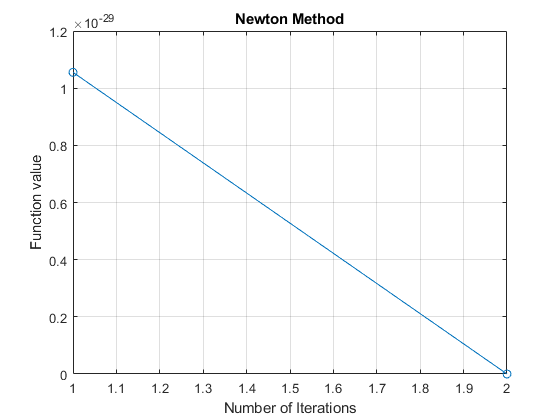

opt = 0

res =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


[opt, res] = newtons(@f1, @g1, @H1, x1, 2, 1e-4)% 0

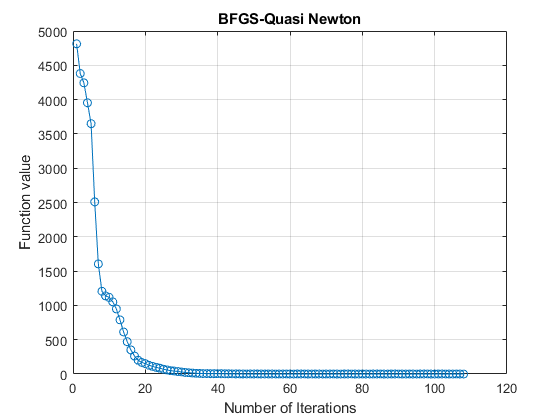

opt = 1.9108e-06

res = 	1.0e+-3 *

    0.1537
   -0.0672
    0.0776
   -0.0663
   -0.0038
    0.0413
    0.0823
   -0.0194
   -0.0010
   -0.0412


[opt, res] = BFGS(@f1, @g1, x1, 0.1, 1e-4)

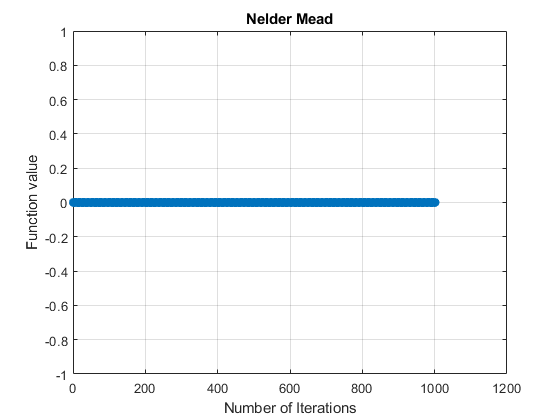

opt = 0

res =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


[opt, res] = nelder_mead(@f1, zeros(100, 1)*0.15, 1e-4)

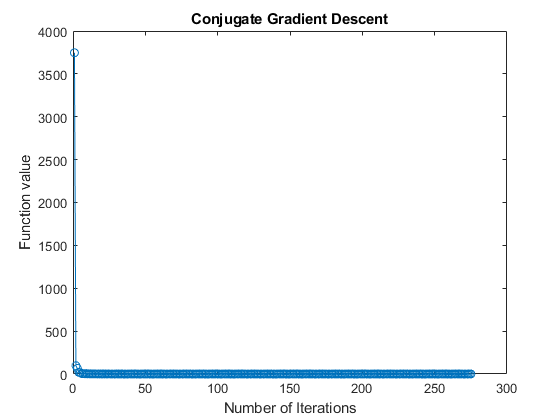

opt = 1.8700e-09

res = 	1.0e+-4 *

    0.4319
   -0.0001
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


[opt, res] = conj_grad(@f1, @g1, x1, 3, 1e-4)

### Funciton 2

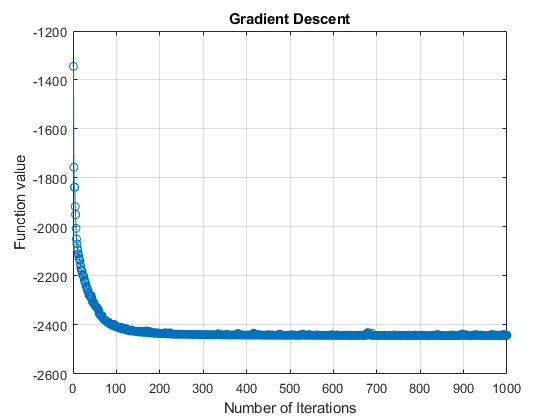

opt = -2.4426e+03

res =    -1.1144
   -1.0983
    1.9821
   -1.6574
    0.4253
    1.9315
   -2.0864
   -0.5673
   -4.0680
   -3.1145


x2 = zeros(100, 1);
f2(A, b, c, x2);

[opt, res] = gradDesc2(@f2, @g2, A, b, c, x2, 2, 1e-4)     

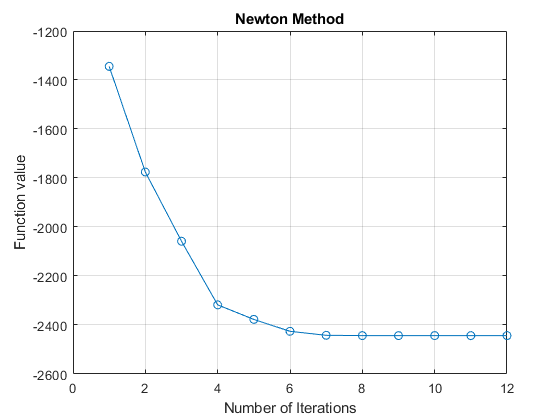

opt = -2.4432e+03

res =    -1.1094
   -1.0697
    1.9717
   -1.6617
    0.4194
    1.9671
   -2.1015
   -0.5844
   -4.0762
   -3.1323


[opt, res] = newtons2(@f2, @g2, @H2, A, b, c, x2, 2, 1e-4)

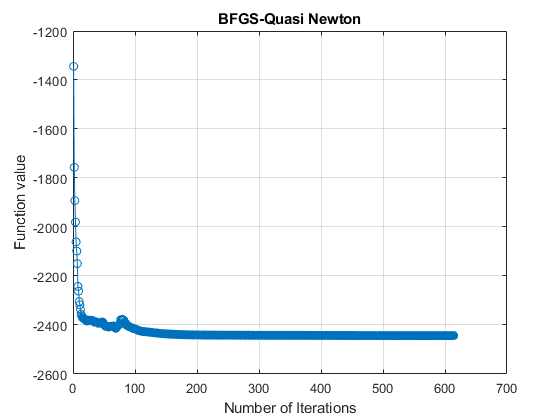

opt = -2.4432e+03

res =    -1.1101
   -1.0692
    1.9722
   -1.6633
    0.4189
    1.9668
   -2.1028
   -0.5853
   -4.0773
   -3.1303


[opt, res] = BFGS2(@f2, @g2, A, b, c, x2, 2, 1e-4)

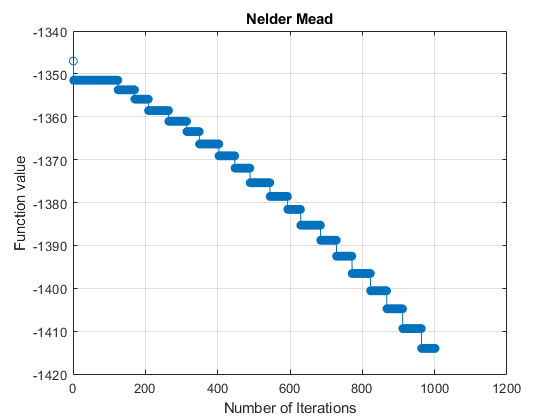

opt = -1.4140e+03

res =    -0.0261
   -0.0859
    0.0885
   -0.0028
    0.0631
   -0.0341
   -0.1708
   -0.0257
   -0.5704
   -0.1022


[opt, res] = nelder_mead(@(x) f2(A, b, c, x), zeros(100, 1), 1e-4) 

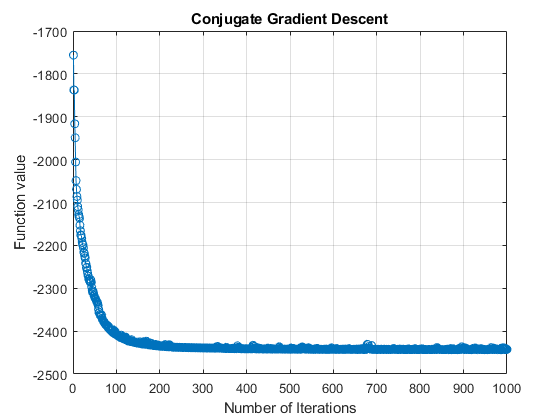

opt = -2.4426e+03

res =    -1.1144
   -1.0983
    1.9821
   -1.6574
    0.4253
    1.9315
   -2.0864
   -0.5673
   -4.0680
   -3.1145


[opt, res] = conj_grad2(@f2, @g2, A, b, c, x2, 2, 1e-4)

### Function 3

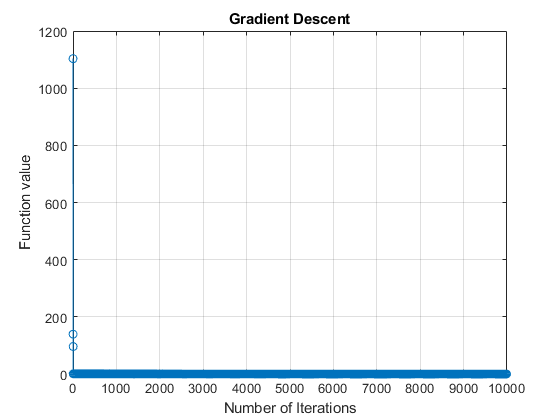

opt = 1.5752e-07

res =     1.0004
    1.0008


x = [3;3];

[opt, res] = gradDesc(@f3, @g3, x, 2, 1e-4)

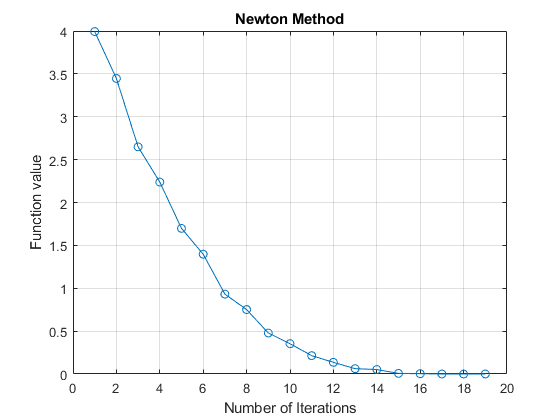

opt = 2.2775e-16

res =     1.0000
    1.0000


[opt, res] = newtons(@f3, @g3, @H3, x, 1, 1e-4)

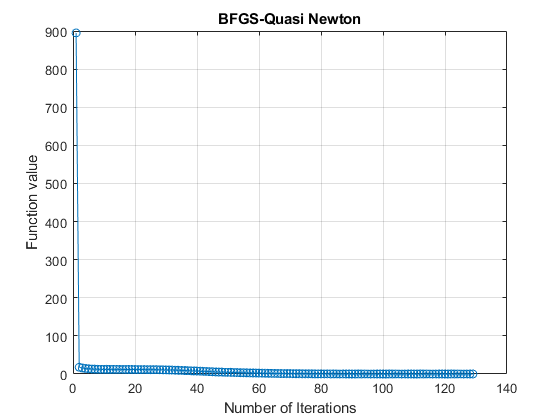

opt = 3.2176e-08

res =     0.9998
    0.9996


[opt, res] = BFGS(@f3, @g3, x, 0.2, 1e-4)

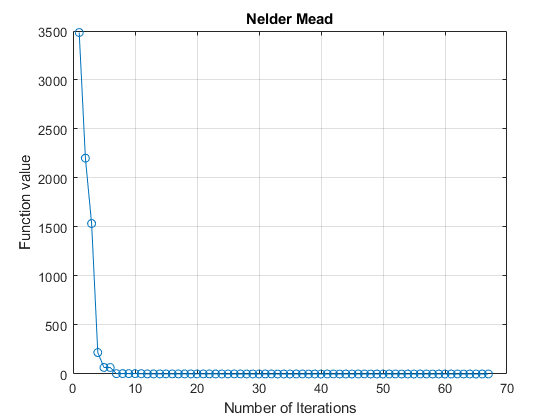

opt = 2.7784e-04

res =     1.0133
    1.0277


[opt, res] = nelder_mead(@f3, [3;3], 1e-4)

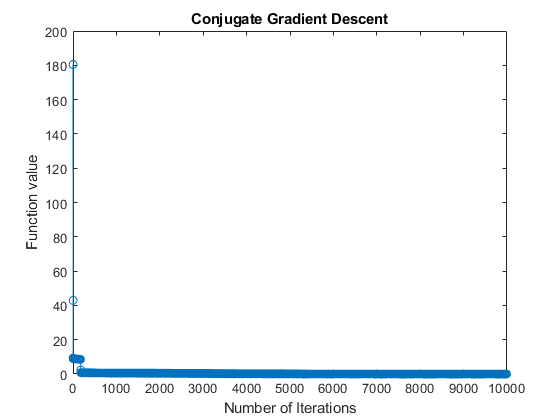

opt = 2.4530e-05

res =     1.0050
    1.0099


[opt, res] = conj_grad(@f3, @g3, x, 3, 1e-4)